addpath('models');
addpath('tests');
addpath('animated_chaff');
addpath('visuals');
addpath('tests');
addpath(genpath('utils'));
addpath(genpath('classes'));


% test of rcs_discrete 

lambda = 0.032;  % Radar wavelength in meters (for 9.4 GHz)
N = 1000;
L_mean = lambda / 2;
L_std = L_mean * 0.2;
spread_sigma = 2;
radar_vec = [1; 0; 0];
pol_vec = [0; 1; 0];

sigma = stat_mc_rcs(N, lambda, L_mean, L_std, spread_sigma, radar_vec, pol_vec);
disp(['Total chaff cloud RCS: ', num2str(sigma), ' m^2']);

Total chaff cloud RCS: 1667.2112 m^2




%Each dipole has a random 3D orientation
%Each dipole has a length drawn from a Gaussian
%The radar wave has a defined direction and polarisation
%RCS is summed from each dipole based on the angular relationship to the polarisation

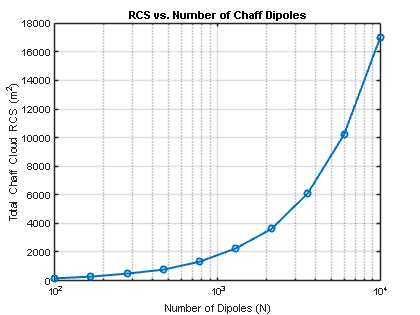

%% RCS vs. Number of Dipoles

lambda = 0.032;              % Radar wavelength (m)
L_mean = lambda / 2;         % Half-wave dipole
L_std = L_mean * 0.2;        % 20% variation in dipole length
spread_sigma = 2;            % Chaff cloud standard deviation (m)
radar_vec = [1; 0; 0];       % Radar incident direction
pol_vec = [0; 1; 0];         % Radar polarisation direction

N_values = round(logspace(2, 4, 10));  % Dipole counts: 100 → 10,000 (log scale)
rcs_values = zeros(size(N_values));

for i = 1:length(N_values)
    rcs_values(i) = stat_mc_rcs(N_values(i), lambda, L_mean, L_std, spread_sigma, radar_vec, pol_vec);
end

figure;
semilogx(N_values, rcs_values, '-o', 'LineWidth', 2);
xlabel('Number of Dipoles (N)');
ylabel('Total Chaff Cloud RCS (m^2)');
title('RCS vs. Number of Chaff Dipoles');
grid on;


%Sweeps N from 100 to 10,000 dipoles (logarithmic steps)
%Calls your compute_rcs_discrete function at each step
%Plots total RCS vs. N

This plot shows the total radar cross-section (RCS) of a chaff cloud as a function of the number of dipole elements (`N`) in the cloud. Each dipole reflects radar energy independently based on its length and orientation relative to the radar's polarisation. The observed trend is approximately nonlinear and increasing, which is expected. This is because:

- Each additional dipole adds to the total scattered energy, and while the orientation-induced variation causes fluctuations, the overall contribution grows with more scatterers.

- For incoherent scattering (which we're assuming), the total RCS scales roughly linearly with N if dipole properties are statistically similar. In this model, length and angle randomness slightly disturb perfect linearity.

- The curvature of the plot reflects a mix of constructive orientation effects and the quadratic dependence on dipole length L2L^2L2 in the RCS formula. 

In real scenarios, mutual coupling, cloud geometry, and coherent effects would flatten this curve at high N, but this model gives a useful upper-bound baseline.

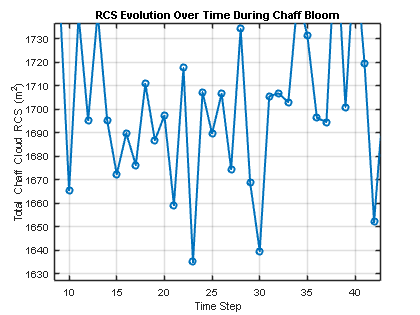

%% Time-Evolving RCS with Function

% Parameters
N = 1000;
lambda = 0.032;
L_mean = lambda / 2;
L_std = L_mean * 0.2;
spread_0 = 0.5;
spread_rate = 0.2;
T = 50;
radar_vec = [1; 0; 0];
pol_vec = [0; 1; 0];

[time, rcs_over_time] = stat_mc_simulate_time(N, lambda, L_mean, L_std, ...
                                                spread_0, spread_rate, T, ...
                                                radar_vec, pol_vec);

% Plot
figure;
plot(time, rcs_over_time, '-o', 'LineWidth', 2);
xlabel('Time Step');
ylabel('Total Chaff Cloud RCS (m^2)');
title('RCS Evolution Over Time During Chaff Bloom');
grid on;

This plot shows the total radar cross-section (RCS) of a simulated chaff cloud over time as the cloud spatially disperses. Although the positional spread (`spread_\sigma`) increases with each time step, the RCS remains relatively stable and fluctuates around a mean value. This is expected because the dipole orientations are randomly resampled at each step, and dipole position is not currently factored into RCS calculation. As a result, the overall scattering characteristics do not evolve meaningfully with cloud size alone.

To observe a more realistic "bloom" effect, future simulations will incorporate orientation drift, decay mechanisms, and spatial filtering based on radar beam geometry.

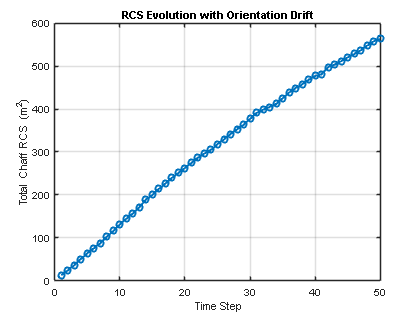

%% Orientation Drift Simulation

N = 1000;
lambda = 0.032;
L_mean = lambda / 2;
L_std = L_mean * 0.2;
spread_sigma = 2;  % Still not used here, but included for future
T = 50;
drift_strength = 0.05;  % Try values like 0.01 to 0.1
radar_vec = [1; 0; 0];
pol_vec = [0; 1; 0];

[time, rcs_drift] = stat_mc_simulate_drift(N, lambda, L_mean, L_std, ...
    spread_sigma, T, drift_strength, radar_vec, pol_vec);

% Plot
figure;
plot(time, rcs_drift, '-o', 'LineWidth', 2);
xlabel('Time Step');
ylabel('Total Chaff RCS (m^2)');
title('RCS Evolution with Orientation Drift');
grid on;

This plot shows the RCS of a chaff cloud over time as individual dipoles gradually drift from an initial uniform orientation. Each dipole starts aligned horizontally and receives a small 3D perturbation vector at each timestep, simulating natural tumbling behavior. The new drift method models these small, continuous orientation changes using additive vector noise, which is commonly used to approximate real-world rotational dynamics in cluttered or turbulent environments. As more dipoles become misaligned with the radar polarisation vector, the overall RCS increases.

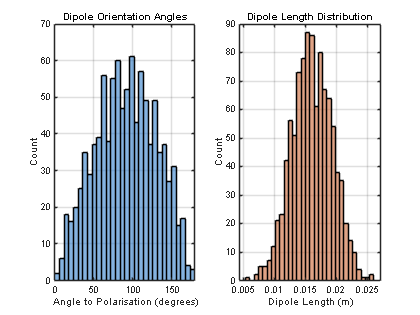

% === Generate test dipole cloud for histogram ===
N_stat = 1000;
lambda = 0.032;
L_mean = lambda / 2;
L_std = L_mean * 0.2;
pol_vec = [0; 1; 0];  % Radar polarisation direction (Y-axis)

% Dipole lengths (Gaussian distribution)
L_stat = L_mean + L_std * randn(N_stat, 1);
L_stat = max(L_stat, lambda / 10);  % Clip minimum for physical realism

% Random 3D orientations (unit vectors)
orientations_stat = randn(N_stat, 3);
orientations_stat = orientations_stat ./ vecnorm(orientations_stat, 2, 2);

% === Call the histogram plotting function ===
stat_mc_plot_histograms(orientations_stat, L_stat, pol_vec);

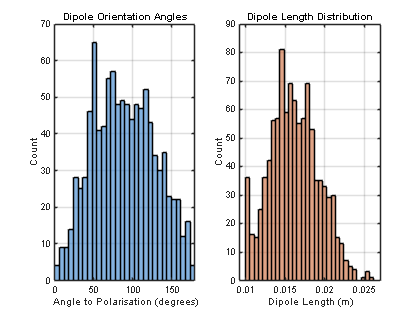

% === Generate test dipole cloud for histogram (with min length) ===
N_stat = 1000;
lambda = 0.032;
L_mean = lambda / 2;
L_std = L_mean * 0.2;
pol_vec = [0; 1; 0];  % Radar polarisation

% Dipole lengths with new min threshold (1 cm = 0.01 m)
L_stat = L_mean + L_std * randn(N_stat, 1);
L_stat = max(L_stat, 0.01);  % Enforce minimum dipole length

% Random 3D orientations
orientations_stat = randn(N_stat, 3);
orientations_stat = orientations_stat ./ vecnorm(orientations_stat, 2, 2);

% Plot updated histograms
stat_mc_plot_histograms(orientations_stat, L_stat, pol_vec);

This analysis visualises the orientation and length distribution of a statistically generated chaff cloud. Dipole lengths are sampled from a Gaussian distribution centered around λ/2, where λ=0.032 m for a 9.4 GHz radar. To reflect physical realism, a minimum dipole length of λ/4 is enforced. This avoids including very short dipoles that contribute negligibly to radar cross-section (RCS), as RCS scales with the square of dipole length. The orientation histogram shows a uniform angular distribution, as expected for a randomly dispersed cloud.

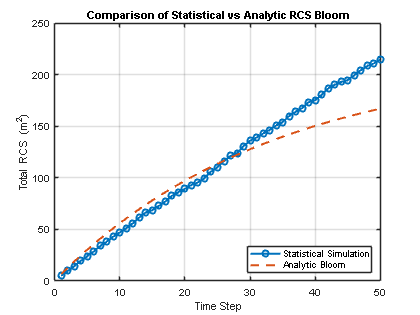

%% Compare Statistical RCS Simulation to Analytic Bloom Model

% === Simulation Parameters ===
N_stat = 1000;
lambda = 0.032;
L_mean = lambda / 2;
L_std = L_mean * 0.2;
spread_sigma = 2;
T_stat = 50;
drift_strength = 0.03;
radar_vec = [1; 0; 0];
pol_vec = [0; 1; 0];

% === Run statistical RCS simulation with drift ===
[time, rcs_stat_time] = stat_mc_simulate_drift( ...
    N_stat, lambda, L_mean, L_std, ...
    spread_sigma, T_stat, drift_strength, radar_vec, pol_vec);

% === Generate analytic exponential bloom curve ===
% Use the sim peak as a rough target for sigma_inf
sigma_inf = max(rcs_stat_time);  % Asymptotic RCS
k = 0.03;                         % Bloom rate (tune this)

rcs_analytic = analytic_bloom_rcs(time, sigma_inf, k);

% === Plot Comparison ===
figure;
plot(time, rcs_stat_time, '-o', 'LineWidth', 2);
hold on;
plot(time, rcs_analytic, '--', 'LineWidth', 2);
xlabel('Time Step');
ylabel('Total RCS (m^2)');
legend('Statistical Simulation', 'Analytic Bloom', 'Location', 'southeast');
title('Comparison of Statistical vs Analytic RCS Bloom');
grid on;

This comparison overlays the radar cross-section (RCS) obtained from a statistical Monte Carlo simulation with a classical analytic "bloom" model, where RCS evolves exponentially toward a maximum value. The analytic model assumes an immediate onset of orientation diversity, whereas the statistical model simulates gradual decorrelation due to dipole drift over time. By adjusting the bloom rate parameter kkk, the analytic curve can be tuned to approximate the simulated behavior, providing a fast yet reasonably accurate alternative for high-level modeling or control systems.

% Parameters
lambda = 0.032;
L = lambda / 2;  % Resonant dipole
%orientation = [0; 1; 0];  % Dipole aligned with y-axis
orientation = [1; 0; 0];  % Dipole perpendicular to y-axis
pol_vec = [0; 1; 0];      % Radar polarisation along y-axis


% Compute single dipole scattering
[sigma, theta_deg, effectiveness] = em_scatter_single_dipole(L, orientation, lambda, pol_vec);

fprintf('RCS: %.4f m²\nAngle to polarisation: %.2f°\nEffectiveness: %.3f\n', ...
    sigma, theta_deg, effectiveness);

RCS: 2.4674 m²
Angle to polarisation: 90.00°
Effectiveness: 1.000


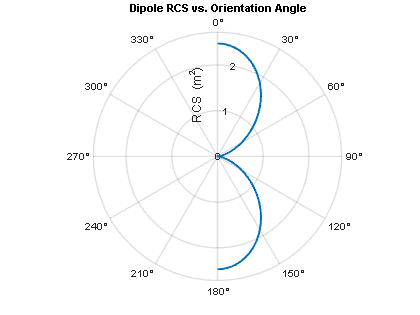

run('visuals/plot_rcs_polar_dipole.m')

This polar plot shows how the radar cross section (RCS) of a single resonant dipole varies with its orientation relative to the radar’s polarisation vector. The RCS is maximized when the dipole is perpendicular to the E-field direction (0° and 180°), and drops to zero when aligned (90° and 270°), consistent with the expected sin 2(θ)\sin^2(\theta)sin2(θ) scattering profile.

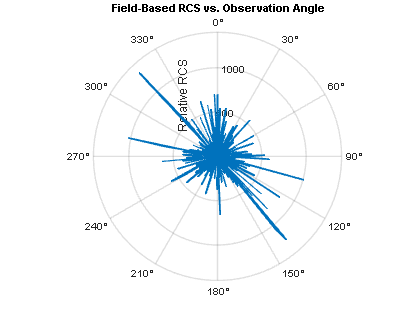

%% Test: Field-Based RCS from Dipole Cloud (EM Scattering)

% Parameters
lambda = 0.032;
N = 300;
L_mean = lambda / 2;
L_std = L_mean * 0.2;
pol_vec = [0 1 0];  % Radar polarisation
R = 1;              % Assume normalized radius for observation direction

% Generate random cloud
positions = 1.5 * randn(N, 3);
orientations = randn(N, 3);
orientations = orientations ./ vecnorm(orientations, 2, 2);

% Sweep radar observation angles (in x-y plane)
theta_deg = linspace(0, 360, 360);
rcs_vals = zeros(size(theta_deg));

for i = 1:length(theta_deg)
    theta_rad = deg2rad(theta_deg(i));
    
    % Observation direction unit vector (in x-y plane)
    r_hat = [cos(theta_rad), sin(theta_rad), 0];

    % Compute complex field
    E_total = em_scatter_field_sum(positions, orientations, lambda, pol_vec, r_hat);

    % Convert to RCS (arbitrary scale)
    rcs_vals(i) = abs(E_total)^2;
end

% Plot polar RCS
figure;
polarplot(deg2rad(theta_deg), rcs_vals, 'LineWidth', 2);
title('Field-Based RCS vs. Observation Angle');
ax = gca;
ax.ThetaZeroLocation = 'top';
ax.ThetaDir = 'clockwise';
ax.RAxis.Label.String = 'Relative RCS';

The plot to the right shows the radar cross section (RCS) of a chaff cloud computed using a field-based coherent scattering model. Each dipole contributes a complex electric field to the radar, with phase determined by its position. As a result, the total RCS fluctuates rapidly with angle due to constructive and destructive interference effects. This angular "speckling" is typical in coherent radar returns from randomly distributed scatterers and reflects the phase-sensitive nature of field summation.

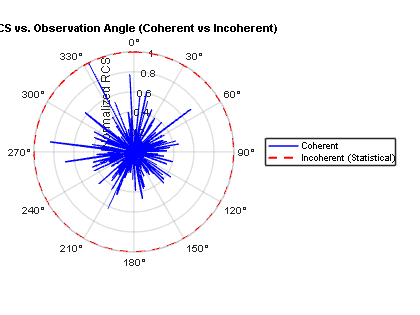

%% Compare Coherent vs Incoherent RCS from Dipole Cloud

% Parameters
lambda = 0.032;
N = 300;
L_mean = lambda / 2;
L_std = L_mean * 0.2;
pol_vec = [0 1 0];  % Radar polarisation (y-axis)

% Dipole cloud
positions = 1.5 * randn(N, 3);
orientations = randn(N, 3);
orientations = orientations ./ vecnorm(orientations, 2, 2);

% Observation angles (in x-y plane)
theta_deg = linspace(0, 360, 360);
rcs_coherent = zeros(size(theta_deg));
rcs_incoherent = zeros(size(theta_deg));

% Loop over angles
for i = 1:length(theta_deg)
    theta_rad = deg2rad(theta_deg(i));
    r_hat = [cos(theta_rad), sin(theta_rad), 0];

    % === Coherent model ===
    E_total = em_scatter_field_sum(positions, orientations, lambda, pol_vec, r_hat);
    rcs_coherent(i) = abs(E_total)^2;

    % === Incoherent model (power sum) ===
    % No phase summation: just total scattered power
    cos_thetas = sum(orientations .* pol_vec, 2);
    cos_thetas = max(min(cos_thetas, 1), -1);
    A = sqrt(1 - cos_thetas.^2);  % ∝ sin(theta)
    rcs_incoherent(i) = sum(A.^2);  % Power sum
end

% Normalize for comparison
rcs_coherent = rcs_coherent / max(rcs_coherent);
rcs_incoherent = rcs_incoherent / max(rcs_incoherent);

%% Plot polar comparison
figure;
polarplot(deg2rad(theta_deg), rcs_coherent, 'b', 'LineWidth', 1.5); hold on;
polarplot(deg2rad(theta_deg), rcs_incoherent, 'r--', 'LineWidth', 2);
title('RCS vs. Observation Angle (Coherent vs Incoherent)');
legend('Coherent', 'Incoherent (Statistical)');
ax = gca;
ax.ThetaZeroLocation = 'top';
ax.ThetaDir = 'clockwise';
ax.RAxis.Label.String = 'Normalized RCS';

This polar plot compares the radar cross section (RCS) of a chaff cloud using two different models.

The blue curve shows the RCS computed using a coherent field summation approach, where the phase of each dipole’s scattered field is taken into account. The result is a spiky, angle-dependent pattern caused by constructive and destructive interference — a characteristic feature of coherent scattering from distributed targets.

The red dashed curve shows the incoherent (statistical) RCS, calculated by summing the power contributions from each dipole independently. This results in a much smoother angular response that approximates the average scattering behavior.

The comparison highlights how phase coherence significantly affects angular variability, and reinforces the value of using both models depending on context — e.g., fast statistical evaluation vs. fine-grained angular analysis.

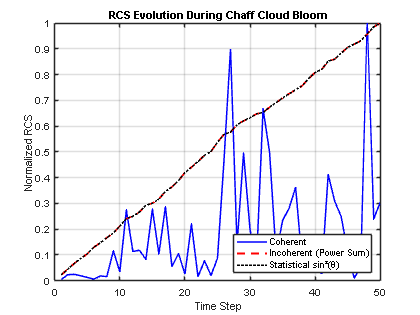

run('tests/test_cloud_rcs_vs_time.m');

The figure above shows the radar cross section (RCS) evolution of a chaff cloud over time using three different models. As the cloud spreads and dipoles reorient, the coherent model exhibits significant fluctuations due to interference effects among phase-shifted contributions from each dipole. The incoherent model (power summation) provides a smooth baseline, reflecting overall scattered energy without phase sensitivity. The statistical model based on sin²(θ) serves as a computationally efficient estimate that tracks dipole orientation alignment with the radar’s polarisation.

This comparison highlights how different modeling assumptions affect predicted RCS — and why coherent modeling is essential when angular or phase-sensitive effects are of interest.

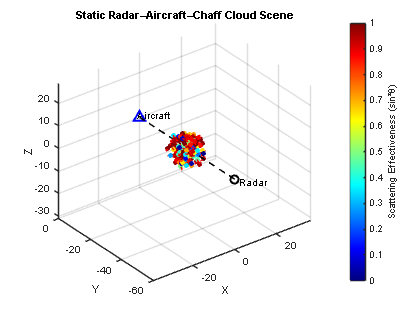

run('tests/test_static_scene_visual.m');

This figure shows a static 3D scene representing an aircraft, radar, and a deployed chaff cloud. The radar line-of-sight is visualized as a dashed beam extending toward the aircraft. The chaff dipoles are randomly distributed around a release point and colored by their scattering effectiveness based on alignment with the radar’s polarisation vector. This visual forms the foundation for later occlusion and optimisation analysis.

Occlusion Test Summary (Precomputed)

A basic line-of-sight (LOS) occlusion check was implemented to evaluate how much of the radar's beam toward the aircraft intersects with the chaff cloud. In this scenario, approximately 41% of dipoles lie within a cylindrical beam corridor, indicating partial obstruction. This geometric screening complements RCS-based measures of chaff effectiveness and lays the groundwork for combined visibility scoring.

Saving GIF frame to: C:\Users\lucia\OneDrive\Documents\MATLAB\chaff_rcs_project\figures\chaff_release_scene_20250507_015150.gif
Saving GIF frame to: C:\Users\lucia\OneDrive\Documents\MATLAB\chaff_rcs_project\figures\chaff_release_scene_20250507_015150.gif
Saving GIF frame to: C:\Users\lucia\OneDrive\Documents\MATLAB\chaff_rcs_project\figures\chaff_release_scene_20250507_015150.gif
Saving GIF frame to: C:\Users\lucia\OneDrive\Documents\MATLAB\chaff_rcs_project\figures\chaff_release_scene_20250507_015150.gif
Saving GIF frame to: C:\Users\lucia\OneDrive\Documents\MATLAB\chaff_rcs_project\figures\chaff_release_scene_20250507_015150.gif
Saving GIF frame to: C:\Users\lucia\OneDrive\Documents\MATLAB\chaff_rcs_project\figures\chaff_release_scene_20250507_015150.gif
Saving GIF frame to: C:\Users\lucia\OneDrive\Documents\MATLAB\chaff_rcs_project\figures\chaff_release_scene_20250507_015150.gif
Saving GIF frame to: C:\Users\lucia\OneDrive\Documents\MATLAB\chaff_rcs_project\figures\chaff_release_sc

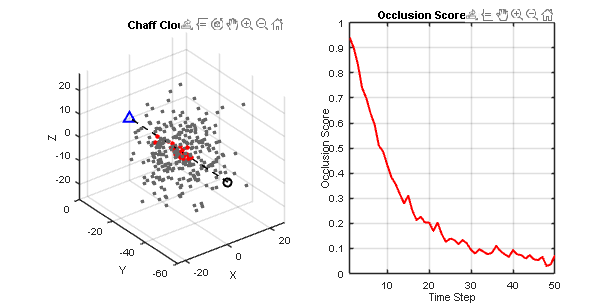

✅ Saved figure to: C:\Users\lucia\OneDrive\Documents\MATLAB\chaff_rcs_project\figures\occlusion_vs_time_20250508_234715.png


run('tests/test_occlusion_over_time.m');

The figure shows the occlusion score of a chaff cloud over time. As the cloud disperses after deployment, the fraction of dipoles intercepting the radar’s line-of-sight to the aircraft decreases significantly. This demonstrates the time-limited nature of chaff effectiveness for geometric masking and underscores the importance of correct deployment timing.

Saving GIF frame to: C:\Users\lucia\OneDrive\Documents\MATLAB\chaff_rcs_project\figures\chaff_release_scene_20250507_015150.gif
Saving GIF frame to: C:\Users\lucia\OneDrive\Documents\MATLAB\chaff_rcs_project\figures\chaff_release_scene_20250507_015150.gif
Saving GIF frame to: C:\Users\lucia\OneDrive\Documents\MATLAB\chaff_rcs_project\figures\chaff_release_scene_20250507_015150.gif
Saving GIF frame to: C:\Users\lucia\OneDrive\Documents\MATLAB\chaff_rcs_project\figures\chaff_release_scene_20250507_015150.gif
Saving GIF frame to: C:\Users\lucia\OneDrive\Documents\MATLAB\chaff_rcs_project\figures\chaff_release_scene_20250507_015150.gif
Saving GIF frame to: C:\Users\lucia\OneDrive\Documents\MATLAB\chaff_rcs_project\figures\chaff_release_scene_20250507_015150.gif
Saving GIF frame to: C:\Users\lucia\OneDrive\Documents\MATLAB\chaff_rcs_project\figures\chaff_release_scene_20250507_015150.gif
Saving GIF frame to: C:\Users\lucia\OneDrive\Documents\MATLAB\chaff_rcs_project\figures\chaff_release_sc

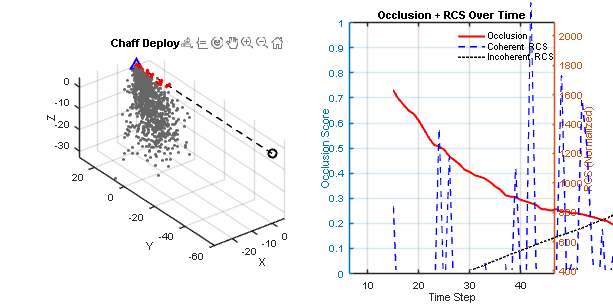

Saving GIF frame to: C:\Users\lucia\OneDrive\Documents\MATLAB\chaff_rcs_project\figures\chaff_release_scene_20250507_015150.gif
✅ Saved figure to: C:\Users\lucia\OneDrive\Documents\MATLAB\chaff_rcs_project\figures\effectiveness_score_20250508_234750.png


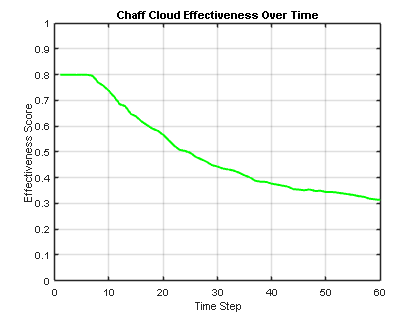

✅ Saved figure to: C:\Users\lucia\OneDrive\Documents\MATLAB\chaff_rcs_project\figures\chaff_release_occlusion_20250508_234751.png


run('tests/test_chaff_release_dynamics.m');

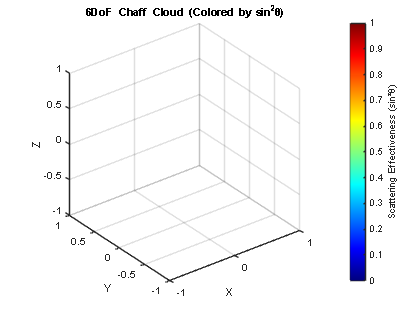

✅ Saved figure to: C:\Users\lucia\OneDrive\Documents\MATLAB\chaff_rcs_project\figures\cloud_sixdof_visual_20250508_234753.png


% === Parameters ===
N = 200;
dt = 0.01;
maxTime = 5;
V = 30;                   % Initial chaff ejection speed
radius = 0.015;           % Dipole radius (m)
rho = 8;                  % Air density
f = 0.1;                  % Lift coeff factor
a1 = 1.5;                 % Drag factor
g = 9.81;

% === Generate 6DoF cloud ===
[positions, orientations, lengths] = generate_6dof_chaff_cloud(N, dt, maxTime, V, radius, rho, f, a1, g);

✅ Saved figure to: C:\Users\lucia\OneDrive\Documents\MATLAB\chaff_rcs_project\figures\cloud_sixdof_visual_20250508_234755.png


[positions, orientations, lengths] = generate_6dof_chaff_cloud(300, 0.1, 5, 30, 0.03, 8, 0.1, 1.5, 9.81);

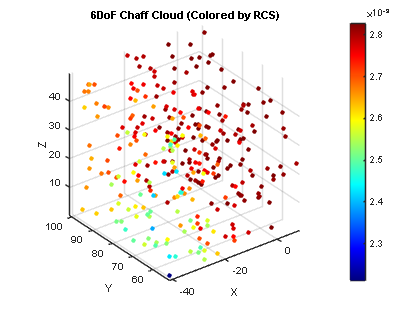

✅ Saved figure to: C:\Users\lucia\OneDrive\Documents\MATLAB\chaff_rcs_project\figures\cloud_sixdof_rcs_20250508_234757.png


[positions, orientations, rcs] = generate_chaff_cloud_sixdof(300);

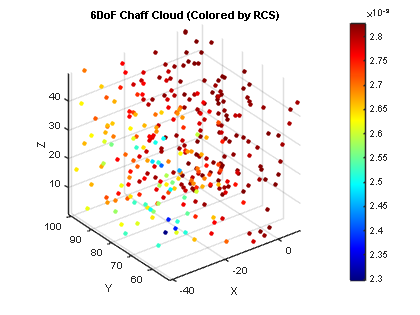

✅ Saved figure to: C:\Users\lucia\OneDrive\Documents\MATLAB\chaff_rcs_project\figures\cloud_sixdof_rcs_20250508_234838.png


[positions, orientations, lengths] = generate_chaff_cloud_sixdof(300);

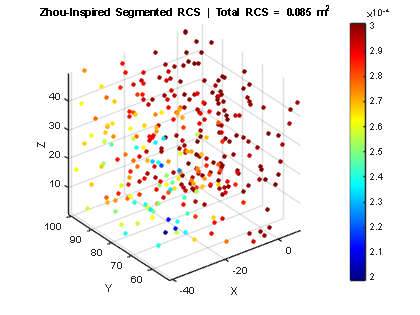

lambda = 0.1;
num_segments = 5;

[rcs_array, total_rcs] = em_rcs_mom_segmented(positions, orientations, lengths, lambda, num_segments);

scatter3(positions(:,1), positions(:,2), positions(:,3), 20, rcs_array, 'filled');
title(sprintf('Zhou-Inspired Segmented RCS | Total RCS = %.3f m^2', total_rcs));
colormap(jet); colorbar;
xlabel('X'); ylabel('Y'); zlabel('Z'); grid on; axis equal;

% % % % % [pos, ori, len] = generate_sixdof_cloud(...);
% % % % % cloud = ChaffCloud(pos, ori, len, 'sixdof');
% % % % % 
% % % % % % Plot with orientation
% % % % % cloud.plot();
% % % % % 
% % % % % % Export
% % % % % cloud.export();


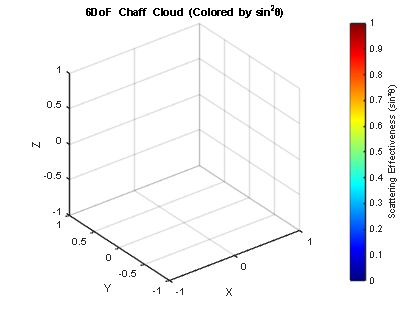

✅ Saved figure to: C:\Users\lucia\OneDrive\Documents\MATLAB\chaff_rcs_project\figures\cloud_sixdof_visual_20250508_235250.png


% Generate a 6DoF chaff cloud with realistic parameters
N = 200;              % Number of chaff fibres
dt = 0.01;            % Time step (s)
T = 5;                % Total simulation time (s)
V = 30;               % Initial velocity (m/s)
radius = 0.03;        % Radius of fibre (m)
rho = 8;              % Air density (kg/m^3)
f = 0.1;              % Proportionality coefficient
a1 = 1.5;             % Distance impact factor
g = 9.81;             % Gravity (m/s^2)

% Generate the cloud
[pos, ori, len] = generate_6dof_chaff_cloud(N, dt, T, V, radius, rho, f, a1, g);

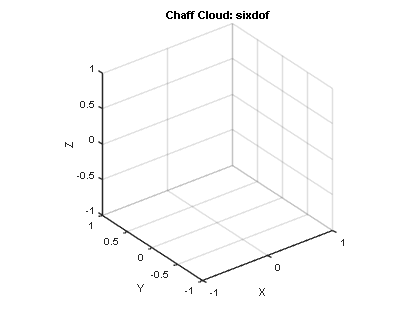



% Construct a ChaffCloud object
cloud = ChaffCloud(pos, ori, len, 'sixdof');


% Plot with orientation arrows and sin²(θ) coloring
cloud.plot();


% Save to figures folder
cloud.export();



% Generate + Store + Plot a Six-DoF Cloud
N = 200; dt = 0.01; T = 5; V = 30; radius = 0.03; rho = 8; f = 0.1; a1 = 1.5; g = 9.81;

[pos, ori, len] = generate_sixdof_cloud(N, dt, T, V, radius, rho, f, a1, g);

Unrecognized function or variable 'generate_sixdof_cloud'.

cloud = ChaffCloud(pos, ori, len, 'sixdof');

cloud.plot();    % Visualize it
cloud.export();  % Save to /figures



